DIRECT STEERING MOBILE ROBOT

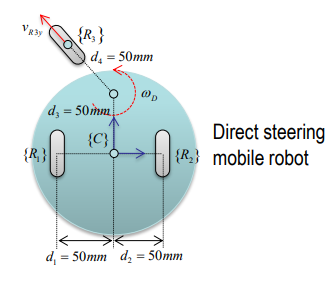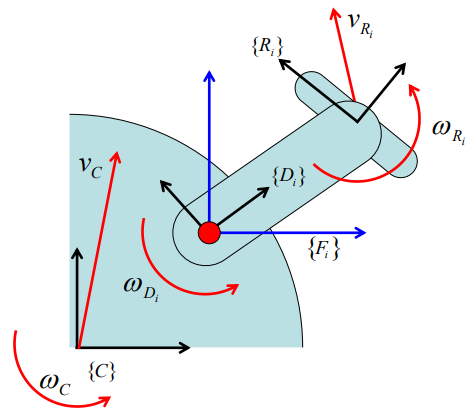

Creamos el Jacobiano sabiendo que son dos ruedas fijas (non-steering) y una rotativa (steering).

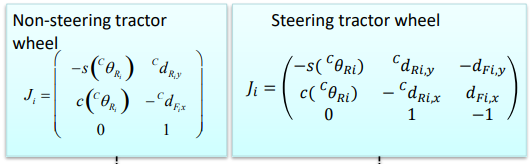

% Sistema {R1}
syms d1 real
alphaF1 = 0;
thetaD1 = 0;
alphaR1 = 0;
dR1 = [0 0 0]';
dF1 = [-d1 0 0]';

J1 = crear_jacob(alphaF1,thetaD1,alphaR1,dR1,dF1,0)

$$J1 = \left(\begin{array}{cc} 0 & 0\\ 1 & d_{1}\\ 0 & 1 \end{array}\right)$$

% Sistema {R2}
syms d2 real
alphaF2 = 0;
thetaD2 = 0;
alphaR2 = 0;
dR2 = [0 0 0]';
dF2 = [d2 0 0]';

J2 = crear_jacob(alphaF2,thetaD2,alphaR2,dR2,dF2,0)

$$J2 = \left(\begin{array}{cc} 0 & 0\\ 1 & -d_{2}\\ 0 & 1 \end{array}\right)$$

% Sistema {R3}
syms Q d3 d4 real
alphaF3 = 0;
alphaR3 = 0;
thetaD3 = Q;
dR3 = [0 d4 0]';
dF3 = [0 d3 0]';

J3 = simplify(crear_jacob(alphaF3,thetaD3,alphaR3,dR3,dF3,1))

$$J3 = \left(\begin{array}{ccc} -\sin\left(Q\right) & d_{3}+d_{4}\,\cos\left(Q\right) & -d_{3}\\ \cos\left(Q\right) & d_{4}\,\sin\left(Q\right) & 0\\ 0 & 1 & -1 \end{array}\right)$$

% Composición
A = [eye(3) ; eye(3) ; eye(3)];
B = [J1 zeros(3,2) zeros(3,3) ; zeros(3,2) J2 zeros(3,3) ; zeros(3,2) zeros(3,2) J3];

d1 = 0.05;
d2 = 0.05;
d3 = 0.05;
d4 = 0.05;

% Deslizamiento MCD
syms v1 v2 v3 w1 w2 w3 real
q_dot = [v1 w1 v2 w2 v3 w3 thetaD3]';

DK = inv(A'*A)*A'*B;
DK = eval(DK);

x = DK*q_dot

$$x = \left(\begin{array}{c} w_{3}\,\left(\frac{\cos\left(Q\right)}{60}+\frac{1}{60}\right)-\frac{\bar{Q}}{60}-\frac{v_{3}\,\sin\left(Q\right)}{3}\\ \frac{v_{1}}{3}+\frac{v_{2}}{3}+\frac{w_{1}}{60}-\frac{w_{2}}{60}+\frac{v_{3}\,\cos\left(Q\right)}{3}+\frac{w_{3}\,\sin\left(Q\right)}{60}\\ \frac{w_{1}}{3}+\frac{w_{2}}{3}+\frac{w_{3}}{3}-\frac{\bar{Q}}{3} \end{array}\right)$$


e = omega(A)*B*q_dot   % Para que no haya deslizamiento, cada elemento = 0.

$$e = \begin{array}{l} \left(\begin{array}{c} \sigma_{1}\\ \frac{v_{2}}{3}-\frac{2\,v_{1}}{3}-\frac{w_{1}}{30}-\frac{w_{2}}{60}+\sigma_{3}+\sigma_{2}\\ \frac{w_{2}}{3}-\frac{2\,w_{1}}{3}+\frac{w_{3}}{3}-\frac{\bar{Q}}{3}\\ \sigma_{1}\\ \frac{v_{1}}{3}-\frac{2\,v_{2}}{3}+\frac{w_{1}}{60}+\frac{w_{2}}{30}+\sigma_{3}+\sigma_{2}\\ \frac{w_{1}}{3}-\frac{2\,w_{2}}{3}+\frac{w_{3}}{3}-\frac{\bar{Q}}{3}\\ \frac{2\,d_{3}\,\bar{Q}}{3}-w_{3}\,\left(\frac{2\,d_{3}}{3}+\frac{2\,d_{4}\,\cos\left(Q\right)}{3}\right)+\frac{2\,v_{3}\,\sin\left(Q\right)}{3}\\ \frac{v_{1}}{3}+\frac{v_{2}}{3}+\frac{w_{1}}{60}-\frac{w_{2}}{60}-\frac{2\,v_{3}\,\cos\left(Q\right)}{3}-\frac{2\,d_{4}\,w_{3}\,\sin\left(Q\right)}{3}\\ \frac{w_{1}}{3}+\frac{w_{2}}{3}-\frac{2\,w_{3}}{3}+\frac{2\,\bar{Q}}{3} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=w_{3}\,\left(\frac{d_{3}}{3}+\frac{d_{4}\,\cos\left(Q\right)}{3}\right)-\frac{d_{3}\,\bar{Q}}{3}-\frac{v_{3}\,\sin\left(Q\right)}{3}\\ \sigma_{2}=\frac{d_{4}\,w_{3}\,\sin\left(Q\right)}{3}\\ \sigma_{3}=\frac{v_{3}\,\cos\left(Q\right)}{3} \end{array}$$

syms Vx Vy Wz d real

VC = [Vx, Vy, Wz]';
IK = inv(B'*B)*B'*A;
IK = eval(IK);

x = IK*VC

e = omega(B)*A*VC

Funciones

function RZ=rotZ(theta)

    s=sin(theta); c=cos(theta);
    if isnumeric(theta)
        if abs(c)<1e-10
            c=0;
        end
        if abs(s)<1e-10
             s=0;
        end
    end 
    
    RZ=[c,-s,0;
        s,c,0;
        0,0,1];
end

function J = crear_jacob(alphaF,thetaD,alphaR,dR,dF,steering_flag)

    CdR = rotZ(alphaF + thetaD) * dR + dF;
    CthetaR = alphaF + thetaD + alphaR;
    
    if steering_flag == 1

        J = [-sin(CthetaR) CdR(2) -dF(2); cos(CthetaR) -CdR(1) dF(1) ; 0 1 -1];

    else
    
        J = [-sin(CthetaR) CdR(2) ; cos(CthetaR) -CdR(1) ; 0 1];
    
    end
end